% % clear all; close all;
% % cd('/Users/natchayasricom/Documents/Project/datasets')
% cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\')
% file = 'A09E.mat';
% load(file);
% cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\true_labels')
% load(file);
% pos_nan = find(isnan(s));
% s(pos_nan) = 0;
% cd('C:\Users\User\Desktop\4-th year project\test')
% 
% eeg = struct;
% 
% % Select channels
% s = s(:,[1:22]);     
% eeg.data = s';
% eeg.data_new = eeg.data;
% 
% % Save important variables
% eeg.fs = h.SampleRate;
% eeg.time = (0:length(eeg.data)-1);
% 
% % Find the NaA values
% 
% LH_po = h.TRIG(find(classlabel == 1));
% RH_po = h.TRIG(find(classlabel == 2));
% % 
% 
% js = 72;
% 
% for i=1:22
%     eeg.fil_data(i,:) = bp_filter(4, 8, 13, eeg.fs, eeg.data_new(i,:));
% end
% 
% 
% % Left hand
% for i=1:length(LH_po)
%     for j=1:22
%         eeg.epoch_data.lh(i,j,:) = [eeg.data_new(j, (LH_po(i)+2*eeg.fs:LH_po(i)+4.999*eeg.fs))] ;
%         EEG.lh(i+js,j,:) = eeg.epoch_data.lh(i,j,:);
%     end
% end
% 
% % Right hand
% for i=1:length(RH_po)
%     for j=1:22
%         eeg.epoch_data.rh(i,j,:) = [eeg.data_new(j, (RH_po(i)+2*eeg.fs:RH_po(i)+4.999*eeg.fs))];
%         EEG.rh(i+js,j,:) = eeg.epoch_data.rh(i,j,:);
%     end
% end



[eeg.train.lh, eeg.test.lh] = split_one_class(lh, 0.9);
[eeg.train.rh, eeg.test.rh] = split_one_class(rh, 0.9);
X = vertcat(eeg.train.lh, eeg.train.rh);
[W, lambda, A] = csp(lh,rh, 3);      % Compute the projection matrix

dim_s1 =     22    22


dim_s2 =     22    22


data_size = size(X);
for i=1:data_size
    x = X(i,:,:);
    x = squeeze(x);   
    Z = W'*x;                         % Transform the X values
    eeg.csp(i,:,:) = Z;
end

X_test = vertcat(eeg.test.lh, eeg.test.rh);
data_test_size = size(X_test);
for i=1:data_test_size(1)
    x_test = X_test(i,:,:);
    x_test = squeeze(x_test);
    Z_test = W'*x_test;
    eeg.csp_test(i,:,:) = Z_test;
end

% train = eeg.csp;
% test = eeg.csp_test;
% save('X_train.mat','train');
% save('X_test.mat','test');

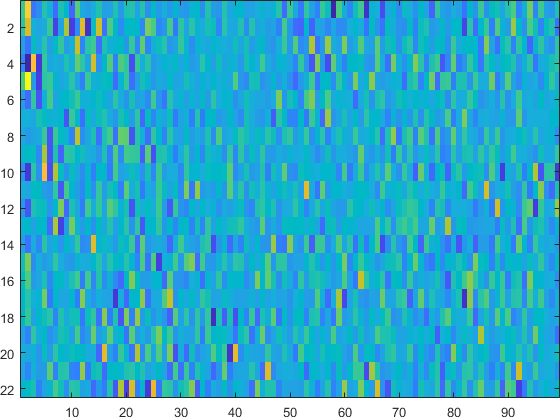

x_p = squeeze(eeg.csp_test(1,:,:));
imagesc(x_p)

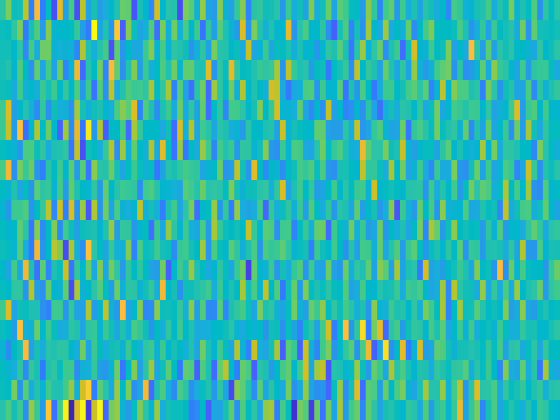

x = 14;
for j=1+x:14+x
    clf;
    sigx = squeeze(eeg.csp_test(j,:,:));
    pcolor(sigx);
    shading flat;
    ax = gca;
    ax.XTick = [];
    ax.YTick = [];
    set(gca,'LooseInset',get(gca,'TightInset'));
    exportgraphics(gca, sprintf('%d.png', j-x));
    colormap parula;
end

function [train, test] = split_one_class(x, percent)
data_size = size(x);
i = data_size(1);               % i = number of trials

i_tr = round(i*percent);
i_te = i - i_tr;

train = x(1:i_tr,:,:);
test = x(i_tr+1 : i_tr + i_te,:,:);
end
% i_tr+1 : i_tr + i_te
function [W, lambda, A] = csp(x1, x2, dim)

% Compute the covarience matrix
if dim==2
    samp_cov_s1 = cov(x1')      % s1~[c x c] 
    samp_cov_s2 = cov(x2')      % s2~[c x c]
else
    data_size = size(x1);
    num_trial = data_size(1);            % i = number of trials
    sum_s1 = 0; sum_s2 = 0;
    for i=1:num_trial
        samp1 = x1(i,:,:); samp1 = squeeze(samp1);
        samp2 = x2(i,:,:); samp2 = squeeze(samp2);
        s1 = cov(samp1');           % s1~[c x c]
        s2 = cov(samp2');           % s2~[c x c]
        sum_s1 = sum_s1 + s1;
        sum_s2 = sum_s2 + s2;
    end

    % Average corvarience of each class 
    samp_cov_s1 = sum_s1/(num_trial-1);
    samp_cov_s2 = sum_s2/(num_trial-1);
end
dim_s1 = size(samp_cov_s1)
dim_s2 = size(samp_cov_s2)

% Solve the eigenvalue problem s1(W) = D(s2)(W)
[W,L] = eig(samp_cov_s1, samp_cov_s1+samp_cov_s2);     % Mixing matrix W (Spatial filters are columes)
[lambda,ind] = sort(diag(L));                          % Sort eigenvalue in descending order
W = W(:,ind);
A = (inv(W))';
end
%%
